# Low lying spectrum and corresponding eigenstates of hydrogen and helium atoms and problem of three interacting electrons 

Temo Vekua

March 29, 2021

This Live Script is intended for physics and chemistry students studying fundamentals of many-body quantum mechanics, and for educators who wish to integrate computation in the foundational quantum mechanics labs. Starting with analytically solvable case of hydrogen atom and reproducing numerically low lying energy spectrum and corresponding wavefunctions, we next study hellium atom with two electrons. Even though for helium atom system sizes studied are small (with $N\le 16$ discrete points in each direction), one can see how explicit numerically exact calculation, without variational approximate methods, suggests shell models to interpret level-structure of many-body problem and leads to parahelium and orthohelium states naturally. The final section is dedicated to constructing many-body wavefucntion obeying Pauli principle for 3 interacting electrons, without decomposing three-body coordinate wavefunctions into the product of single-partical orbitals.

## Numerical simulation of hydrogen atom

Nonrelativistic Hamiltonian describing hydrogen atom at rest can be written as


$$(1) \quad H_{hydrogen}=\frac{m_e}{\hbar^2} \Big(  \frac{e^2}{4\pi\varepsilon_0} \Big)^2\Big( -\frac{a_0^2}{2} \vec \nabla^2 - \frac{a_0}{r}\Big),$$


where $m_e$ is a mass of electron (treating proton mass as infinite), $\hbar$ is a reduced Planck's constant, $e$ is proton's charge, $\varepsilon_0$ is a vacuum permittivity, $r=\sqrt{r_x^2+r_y^2+r_z^2}$ is a distance from the origin (proton's location), $\vec \nabla^2$ is a 3D Laplacian and Bohr radius is


$$(2) \quad a_0=\frac{\hbar^2 4\pi \varepsilon_0 }{m_e e^2}\simeq 0.5  \text{\AA} =0.5\cdot10^{-10}m.$$


Analytical expression of hydrogen atom's $n$-th ($n=1,2,3,\cdots$, with $n=1$ corresponding to the ground state is) bound state energy (without relativistic corrections [1]) is

$(3) \quad E_n=-\frac{m_e}{2 \hbar^2}  \frac{e^4}{(4\pi\varepsilon_0)^2} \frac{1}{n^2}$.

The (coordinate) wavefunction for the lowest energy (ground) state of electron in the hydrogen atom is

$(4) \quad \psi_{0}(\vec r)=\frac{1}{\sqrt{\pi a_0^3}}e^{-r/a_0}$.

The radial probability density in the ground state is

$(5) \quad P_r=4\frac{r^2}{a_0^3}e^{-2r/a_0}$.

Let's plot radial dependencies in Eq. (4) and Eq. (5).

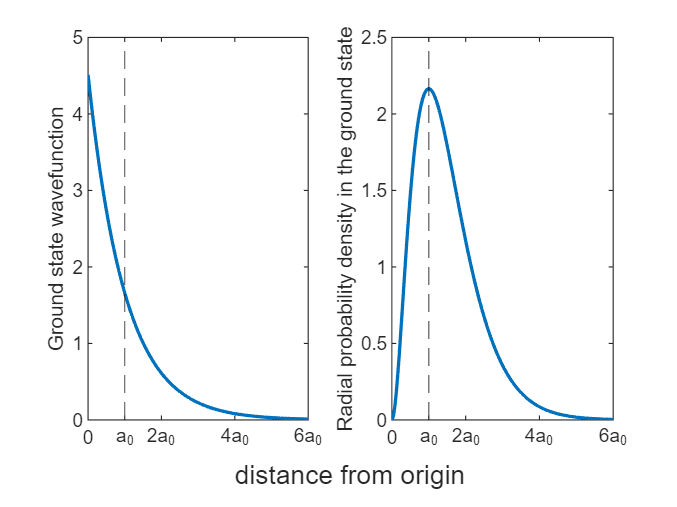

clf;
a_0=1/4; % distance will be measured in units of 4*a0
r=0:0.01:1.5;
clc;
t = tiledlayout(1,2,'TileSpacing','Compact');
nexttile
plot(r, exp(-r/a_0)/sqrt(pi*a_0^3))
xline(a_0,'--k')
xticks([0, a_0, 0.5, 1, 1.5])
xticklabels({'0','a_0', '2a_0','4a_0','6a_0'})
ylabel('Ground state wavefunction')
nexttile
plot(r, 4*r.^2.*exp(-2*r/a_0)/a_0^3)
xline(a_0,'--k')
xticks([0, a_0, 0.5, 1, 1.5])
xticklabels({'0','a_0', '2a_0','4a_0','6a_0'})
ylabel('Radial probability density in the ground state')
xlabel(t,'distance from origin')

integral(@(r) 4*r.^2.*exp(-2*r/a_0)/a_0^3,0,1.4)

ans = 0.9990

With probablility of 99.9% electron is localized within $R=1.4\cdot 4a_0$ sphere in the ground state. This estimate will help us to determine optimal linear length $L$ of 3D mesh for accurate numerical simulation of the ground state wavefunction and energy.

During simulations we will use dimensionless distance $r/(4a_0)\to r$ (distance will be measured in units of four times Bohr radius). We will solve numerically following eigenvalue problem:


$$(*)\quad \Big( -\frac{1}{2} \vec \nabla^2 - \frac{4}{r}\Big) \psi(\vec r) =E\psi(\vec r)$$


and to convert obtained dimensionless energies $E$ into standard energy units we will multiply them by factor:

 $(6) \quad -\frac{E_0}{8}= \frac{m_e}{\hbar^2} \Big(  \frac{e^2}{16\pi\varepsilon_0} \Big)^2$,

equal to $2.72\cdot 10^{-19}J$, or in Electronvolts $1.7eV$, or in hartrees $\frac{1}{16} Ha$.

Let's check that dimension of Eq. (6) is Joule, using symbolic math toolbox .

u = symunit; % create symbolic variable u that carries collection of units
eqn = u.J == u.m_e*u.e^4/(u.hbar^2*u.e_0^2); %u.J carries Joule, dimension of energy in SI
checkUnits(eqn,'Compatible')

Hydrogen atom's bound states occupy more volume with increasing $n$, see [this](https://en.wikipedia.org/wiki/Atomic_orbital) (shell radius grows fast with energy level $n$ as $a_0n^2$). Hence, finite size volume $L^3$ (which we impose to perform numerical simulations) will influence energy of the level more with increasing $n$. In addition, finite-size effects remove Coulomb ($n^2$, without considering spin degrees of freedom) degeneracy of hydrogen energy levels.  

L = 2.8;  % Interval Length in each direction in units of 4 Bohr radia. L=1 is a distance of one 4 Bohr radia, ~2 angstroms
N = 26;  % Number of coordinate points in each direction
x = linspace(-L/2, L/2, N).'; % 1D coordinate column vector
dx = x(2) - x(1); % Coordinate step 

e    = ones(N,1);  % a column of 1-s with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  % sparse NxN matrix with vector -2*e along the main diagonal
% and vector e along upper and lower diagonals, so called 3-point Laplacian

% Below we show two equivalent ways to define 3D Laplacian corresponding to a particle. 
% Both forms are identical to sum of Laplacians of 3 one-dimensional particles

% Lap_2D = kron(Lap_1D,speye(N))+kron(speye(N),Lap_1D); % 2D Laplacian, speye(N) is sparce NxN identity matrix
% H_K3D = -1/2*(kron(Lap_2D,speye(N))+kron(speye(N^2),Lap_1D)); % -1/2 times 3D Laplacian 

Lap_1 = kron(kron(Lap_1D,speye(N)),speye(N)); % sparse N^3xN^3 matrix
Lap_2 = kron(kron(speye(N),Lap_1D),speye(N));
Lap_3 = kron(kron(speye(N),speye(N)),Lap_1D);
H_K3D = -1/2*(Lap_1+Lap_2+Lap_3);

[X,Y,Z]=meshgrid(x);  % X,Y,Z are 3D tensors of size [N,N,N] encoding 3D coordinate grid
% X encodes x coordinates of N^3 lattice points, Y encodes y coordinates and Z -> z
% coordinates
syms x1 x2 x3 y1 y2 y3 z1 z2 z3   % define symbolic variables for better clarity what meshgrid function does
x_s=[x1 x2 x3].'            % define symbolic column
y_s=[y1 y2 y3].'
z_s=[z1 z2 z3].'
[X_s,Y_s, Z_s]=meshgrid(x_s,y_s,z_s)

U=-4./sqrt(X.^2+Y.^2+Z.^2);   % U is three dimensional tensor here with size(U)= [N,N,N], 
% with N^3 elements, number of lattice points in 3D space
U=spdiags(U(:),0, N^3,N^3);   % U becomes sparse diagonal matrix of linear dimension N^3 

H=H_K3D+U;                    % matrix corresponding to the total dimensionless hamiltonian Eq. (*) 
[V,E] = eigs(H,15,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors.

E % show energies 

V_XYZ=reshape(V(:,1)/dx^(3/2),N,N,N); % for plotting reshape eigenfunctions (column vectors) into 3D tensors
V_XY=V_XYZ(:,:,N/2); % selecting Z=0 section
[X2,Y2]=meshgrid(x);
t1=tiledlayout(1,2);
nexttile
surf(X2,Y2,V_XY) %sometimes invert sign in front of V_XY
xlim([-1.4 1.4])
ylim([-1.4 1.4])
zlim([0 4.3])
xlabel(t1, 'unit of spacing is 4a_0')
zlabel('Wavefunction')
title('Simulated wavefunction')
daspect([1 1 1])
psi_0=1/sqrt(pi*0.25^3)*exp(-4*sqrt(X2.^2+Y2.^2+x(N/2)^2)); %analytical expression for a_0=0.25
nexttile
surf(X2,Y2,psi_0)
xlim([-1.4 1.4])
ylim([-1.4 1.4])
zlim([0 4.3])
title('Analytical wavefunction')
daspect([1 1 1])

For $L=20$, and different $N$, energies of first 15 lowest levels are given in the table below (non-converged values for $N=120$ are represented by NaN). Note, with increasing $N$ all values converge to their true thermodynamic limit values.

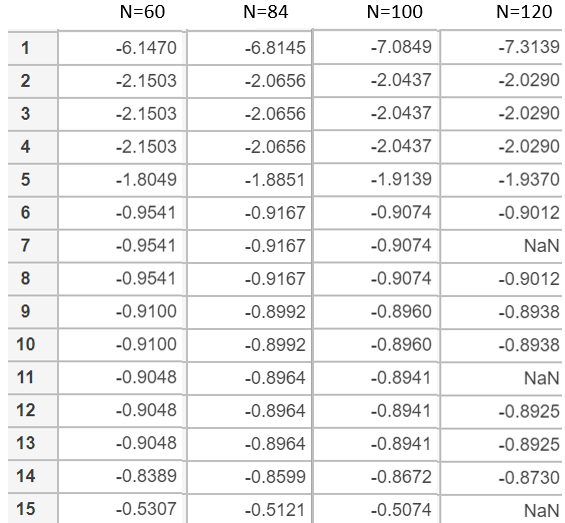

True energy (continuum limit in infinite space) values are  $n=1: E=-8$ (singlet $l=0$ s-state, its enegry converges to $-8$ with increasing $N$, for $N=200$, $E=-7.72$), $n=2, E= -2$ (4 states $l=1$ triplet and $l=0$ singlet) , $n=3, E= -8/9$ (9 states, quintuplet, triplet, and singlet), $n=4, E= -0.5$ (16 states). 

Since electron in the ground state is localized close to the origin (with probablility of 99.9% electron is localized within $r=1.4\cdot 4a_0$ sphere in the ground state), taking $L=2.8$ gives much better matching with true thermodynamic ground state energy value. Already for $N=20$, $E=-7.44$, for $N = 64$, $E=-7.93$, for $N=100$, $E=-7.97$ and for$N=200$, $E=-7.99$. 

tiledlayout(2,2)
for j=2:5
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end

tiledlayout(2,2)
for j=6:9
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end
tiledlayout(2,2)
for j=10:13
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end
tiledlayout(1,2)
for j=14:15
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end


## Numerical simulation of helium atom

Now we trurn to simulation of helium atom with $Z=2$, in the approximation of an infinitely heavy nucleus (neglecting the mass polarization term, which, when neede, is easy to include as it does not increase computational complexity). Contrary to the hydrogen atom case, there is no closed-form solution of the two-electron Schrodinger equation for helium atom, described by following hamiltonian: 


$$(7) \quad H_{helium}=\frac{m_e}{\hbar^2} \Big(  \frac{e^2}{4\pi\varepsilon_0} \Big)^2\Big( -\frac{a_0^2}{2} \vec \nabla_1^2 - -\frac{a_0^2}{2} \vec \nabla_2^2 -\frac{2a_0}{r_1} -\frac{2a_0}{r_2}    +\frac{a_0}{ |\vec r_1-\vec r_2|}\Big).$$


The last term in Eq. (7) describes mutual Coulomb repulsion between the two electrons of helium atom.

We will again use dimensionless distance $r/(4a_0)\to r$ and solve following eigenvalue problem fot he dimensionless hamiltonian:


$$(**) \quad \Big( -\frac{1}{2} \vec \nabla_1^2- \frac{1}{2} \vec \nabla_2^2- \frac{8}{r_1} - \frac{8}{r_2}  +\frac{4}{|\vec r_1-\vec r_2|} \Big) \psi(\vec r_1, \vec r_2) =E\psi(\vec r_1, \vec r_2)$$


and to convert dimensionless energies $E$ obtained from eigenvalue problem Eq. (**) to standard energy units we will multiply them by  a factor given in Eq. (6) (equal to $1.7eV$).

Helium atom hamiltonian given in Eq. (7), acts on the wavefunction that is defined in 6D space (with 3D coordinate space corresponding to each particle). If $N$ is a number of discrete points along each of the spacial direction, then dimension of matrix corresponding to hamiltonian will be $N^6$x$N^6$ and matrix will be real (due to time-invariance of the problem) and hence symmetric (due to hermiticity of matrices corresponding to observables). Eigenvectors of real and symmetric matrices can always be represented by real and orthonormal set of vectors.  

A total two-particle wavefunction (accounting both for coordinate and spin degrees of freedom of two particles) can always be represented as a product of coordinate wavefunction and spin wavefunction (this is not always possible for three and more particles, see section on three electron case below),


$$(8) \quad \Psi^{electrons}_{s_1,s_2}(\vec r_1, \vec r_2)=\psi(\vec r_1, \vec r_2)\sigma(s_1,s_2).$$


Pauili exclusion principle requires antisymmetry under simultaneous exchange of spins and coordinates of electrons

 
$$(9) \quad \Psi^{electrons}_{s_1,s_2}(\vec r_1, \vec r_2)=-  \Psi^{electrons}_{s_2,s_1}(\vec r_2, \vec r_1).$$


In order that such separable (in spin and coordinate parts Eq. (8)) wavefunctions satisfy antisymmetry condition Eq. (9) only two options exist: when exchanging two particles coordinates and spins $r_1 \leftrightarrow r_2, \,\, s_1 \leftrightarrow s_2$ either coordinate wavefunction is symmetric and spin wavefunction is antisymmetric (spin-singlet state $\sigma_0(s_1,s_2)=(|\uparrow_1\rangle\otimes |\downarrow_2\rangle -|\downarrow_1\rangle \otimes |\uparrow_2\rangle)/\sqrt{2}$), or vice verca, coordinate wavefunction is antisymmetric and spin part is symmetric (spin-triplet state).

The eigenvectors of Eq. (**) satisfy the following condition (unless different parity eigenstates are energetically degenerate and computer returns some linear superposition of them without definite parity, cases that can be observed if we switch off Coulomb repulsion between electrons):


$$\psi(\vec r_2, \vec r_1)=\pm \psi(\vec r_1, \vec r_2).$$


We will see that helium's ground state coordinate wavefunction is symmetric with respect to exchanging coordinates of the two electrons $\psi_0(\vec r_1, \vec r_2) =\psi_0(\vec r_2, \vec r_1)$ (no-node in ground state), hence ground state corresponds to parahelium (spin-singlet state). Single-particle desnity shows spherical symmetry (with the caviet that we are using 3D cubic finite lattice for simulations).

Wavefunctions of first few lowest excited states though are antisymmertic with respect to exchanging two electrons' coordinates, hence they correspond to orthohelium (spin-triplet states). These facts have intuitive explanation in shell model. Shell model is based on a single-electron picture: solve for one electron, like in the case of hydrogen atom above, and then distribute many electrons in the energy states of single-electron problem according to Pauli principle with adjusting or distorting, single-electron orbitals variationally. In the ground state of helium both electrons occupy $1s$ lowest orbital, hence they must form spin-singlet state. In the lowest excited states two electrons occupy both$1s$ and $2s$ (with spherical symmetry of single-particle density) or $1s$ and $2p$ (without spherical symmetry of single-particle density) orbitals, spin configurations can be singlet (parahelium) as well as triplet states (orthohelium) for these cases.

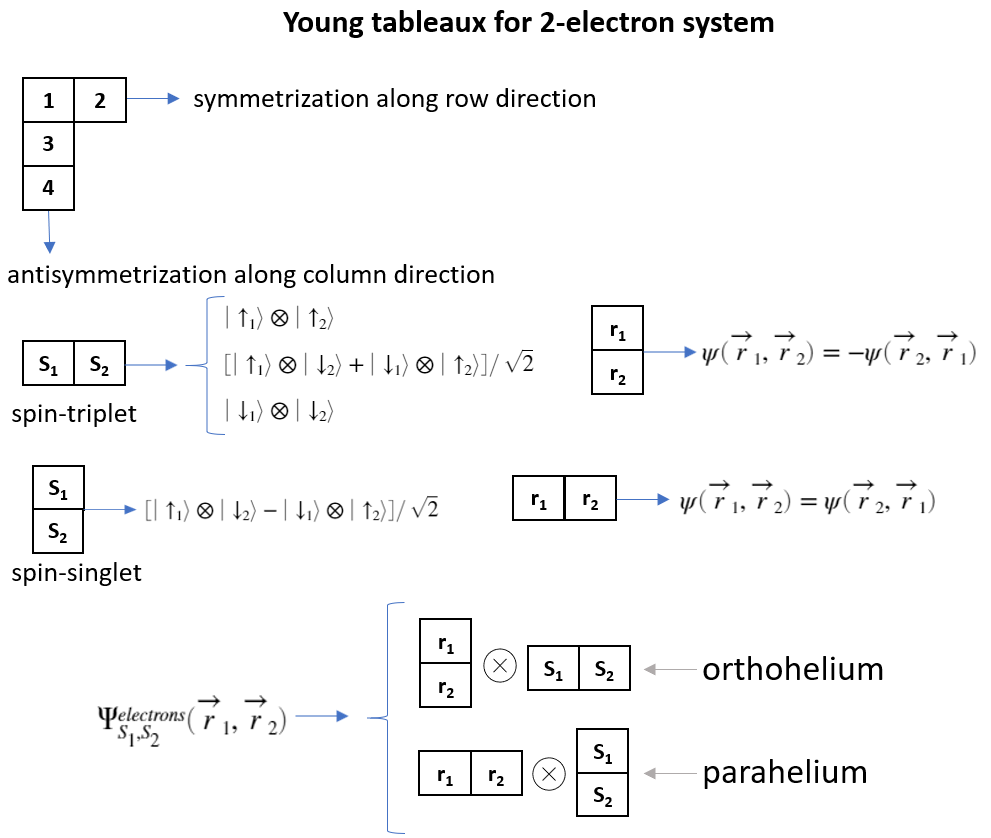

We will also study single-particle (one-body) density in the ground state and the lowest excited states of helium atom,

$(10)\quad \rho_{\alpha}(\vec r)=  \int d^3{\vec r'} |\psi_{\alpha}(\vec r,\vec r')|^2,$ with $\alpha=0$ indicating the ground state. 

$\rho_{\alpha}(\vec r)$ is the probability of finding an electron (when system is described by a two-electron state $\psi_{\alpha}$) in the volume element around vector $\vec r$, whilst another electron is anywhere.

L = 2;  % Interval Length in each direction in units of 4 Bohr radia. L=1 is a distance of 4 Bohr radia, ~2 angstroms
N = 10;  % Number of coordinate points in each direction
x = linspace(-L/2, L/2, N).'; % Coordinate column vector in x direction
dx = x(2) - x(1); % Coordinate step 


e    = ones(N,1); % a column of ones with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;       % 1D Laplacian
Lap_2D = kron(Lap_1D,speye(N))+kron(speye(N),Lap_1D);    % 2D Laplacian
Lap_3D = kron(Lap_2D,speye(N))+kron(speye(N^2),Lap_1D);  % 3D Laplacian 

[X,Y,Z]=meshgrid(x); % three-dimensional mesh
% X, Y and Z are 3-dimensional tensors
U = -8./sqrt(X.^2+Y.^2+Z.^2);   % U here is three dimensional tensor with size(U)= [N,N,N]
U = spdiags( kron(U(:),ones(N^3,1))+kron(ones(N^3,1),U(:)), 0, N^6,N^6);   
% U in left-hand side becomes sparse diagonal matrix of linear dimension N^6, 
% accounting for Coulomb attraction of two electrons by helium nucleus

U_12=4./sqrt(0.0000001+ (kron(X(:),ones(N^3,1))-  kron(ones(N^3,1),X(:))).^2 ... 
    + (kron(Y(:),ones(N^3,1))-  kron(ones(N^3,1),Y(:))).^2 ... 
    +(kron(Z(:),ones(N^3,1))-  kron(ones(N^3,1),Z(:))).^2); % inter-electron interaction
% we choose some small number (1e-7) to avoid a divergence of a matrix when coordinates of 
% two electrons are equal 
H_K   = -(1/2)*(kron(Lap_3D,speye(N^3))+kron(speye(N^3),Lap_3D));
% Kinetic energy part of two electrons
H=H_K+U+spdiags(U_12,0,N^6,N^6);

[V,E] = eigs(H,5,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high.
V = V(:,ind);                  % rearrange corresponding eigenvectors.

E % show energies 

% Next we will calculate single-particle density in ground states of para and orthohelium (in Z=0 plane) and plot it
tiledlayout(1,2)
for j=[1,5] % j=1 is ground state of parahelim, j=5 we expect to becom ground state of orthohelium in thermodynamic limit
    psij=reshape(V(:,j),N^3,N^3);
    rho=diag(psij'*psij);  % this is a lattice version of continuum definition Eq. (10)
    rho=reshape(rho,N,N,N) % reshape to study single-particle density in Z=0 (x-y) plane below
    rho=rho(:,:,N/2);      % single-particle density in Z=0 plane in the state psij
    [X2,Y2]=meshgrid(x);
    nexttile
    surf(X2,Y2,rho/dx^2)
    view([0 90]) % uncomment this line for 2D view
    daspect([1,1,1])
    zlim([0 1.8])
end

tiledlayout(1,3)
for j=2:4 % orbital momentum l=1 states
    psij=reshape(V(:,j),N^3,N^3);
    rho=diag(psij'*psij); 
    rho=reshape(rho,N,N,N);
    rho=rho(:,:,N/2);   % single-particle density in Z=0 plane in the state psij
    [X2,Y2]=meshgrid(x); % encode 2D mesh into X2 and Y2 matrices
    nexttile
    surf(X2,Y2,rho/dx^2)
    view([0 90]) % uncomment this line for 2D view
    daspect([1,1,1]) % equal aspect ration of axes
end


psi0=reshape(V(:,1),N^3,N^3); % reshape into matrix to check symmetry with respect to exchanging electrons' coordinates
psi0 % psi0 is a symmetric matrix, hence it describes ground state of parahelium (and also ground state of helium atom)
psi1=reshape(V(:,2),N^3,N^3);
psi1 % psi1 is an antisymmetric matrix, hence it describes orthohelium
psi2=reshape(V(:,3),N^3,N^3);
psi2 
psi3=reshape(V(:,4),N^3,N^3);
psi3 
psi4=reshape(V(:,5),N^3,N^3);
psi4 

max(max(abs(psi0-psi0.')))  % result is negligibly small number, hence psi_0(r1,r2)=psi_0(r2,r1)  -> parahelium state
max(max(abs(psi1+psi1.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state
max(max(abs(psi2+psi2.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state
max(max(abs(psi3+psi3.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state
max(max(abs(psi4+psi4.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state

In finite systems ($N=10,12,14$ and $L=2$) the first 3 lowest excited states are degenerate in energy and are antisymmetric with respect to $\vec r_1\leftrightarrow \vec r_2$ (hence they should correspond to orthohelium). Single-particle densities show no spherical symmetry in these states, hence presumably these states in thermodynamic limit will converge to $1s2p$ orthohelium states with orbital momentum $l=1$. The fourth excited state (for the same system sizes as above) is a non-degenerate in energy, shows also antisymmetry with respect to $\vec r_1\leftrightarrow \vec r_2$ (hence it also describes orthohelium), however single-particle density calculated in this state shows same symmetry as the parahelium ground state. This state presumably converges in thermodynamic limit to $1s2s$ orthohelium state. Gap between the first three degenerate excited states and fourth non-degenerate state decreases with increasing system size and in accordance with experiments we expect that in thermodynamic limit the ground state in orthohelium configuration will be the non-degenerate $1s2s$ state, antisymetric with respec to $\vec r_1\leftrightarrow \vec r_2$ and with spherically symmetric eletron cloud. Yet, system sizes considered here are too small to make definitive claims for excited states. 

In Fig. 1 we plot single-particle densities in the ground states of parahelium (left) and orthohelium configurations (the latter state for $N=14$ is the fourth excited state).

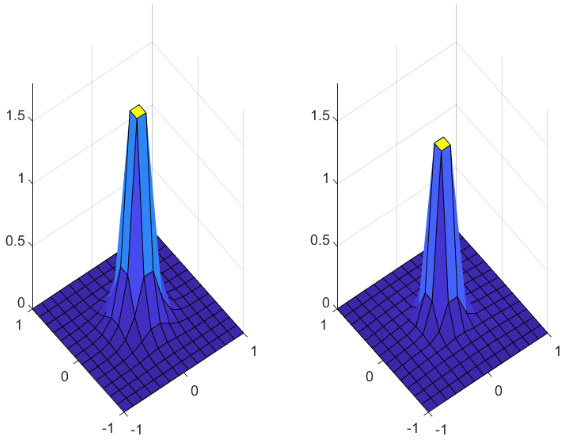

Figure 1: Single particle density in the $x-y$ plane in the ground state of parehelium (left) and orthohelium (right) for $N=14$ and $L=2$. In both cases electron density shows spherical symmetry ($l=0$ orbital momentum states). Particles are localized closer to origin in parahelium.

### Ground state energy of helium atom

Experimentally determined ground state energy of helium atom is equal to $5.8$-times ground state energy of hydrogen atom. Were electrons not interacting with each other, we would have obtained for helium ground state energy $8$-times the ground state energy of hydrogen atom, however Coulomb repulsion between electrons modiifes factor of 8 to 5.8. We will confirm this below. 

Due to exponential scaling of computational complexity with the number of quantum particles, in the case of helium atom we are limited to maximum number of points in each direction to $N_{helium,max }\sim \sqrt{N_{hydrogen, max}}$. On the other hand, electrons in the ground state are more localized to nucleus in helium, than in hydrogen atom. We will use this fact and will take $L=1$ for ground state calculations (3D box with a linear size of $4a_0$) to distribute all available $N_{helium,max}$ in the relevant region.

We calculated ground state energy for different values of $N$ (up to $N=16$ calculations are performed within a few minutes). Obtained results are presented in table below.

 

We introduce $x=1/N$ and fit $E_0$ to $x$ by the simplest linear model Poly1 (using curve fitting toolbox). Results are presented below.

 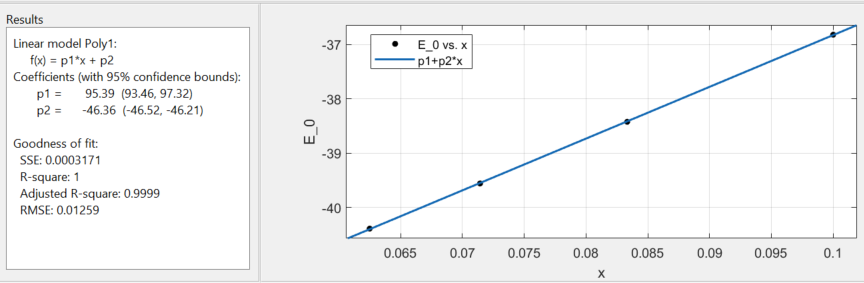

We are interested in thermodynamic limit $x\to 0$, where $E_0=p2$.

Ground state electron configuration energy of helium atom after linear extrapolatin of the results to the thermodynamic ($N\to \infty$) limit, within 95% confidence bounds is ($-78.5893eV$, $-79.1166eV$).  Experimentally determined ground state energy of the helium atom, −79.005151042(40) eV [2], falls within these bounds as a lucky coincidence.

## Three-electron problem

For 3 and more electrons (Lithium and heavier atoms) analogous to Eq. (**) 3D eigenvalue problems are computationally too heavy (for 3 electrons problem, hamiltonian matrix dimensions are $N^9$x $N^9$, daunting already for $N=10$) and approximate, but accurate variational methods or methods such as Kohn-Sham DFT  [3] (both in momentum and in real space formulations) exist. These approximate methods give very good description also for helium atom, and, since they are effectivey single-particle approaches, they are not plagued with exponential growth of the Hilbert space dimension with number of particles. 

 For 3 and more electrons hamiltonian matrix again will be real and symmetric, hence it will have a complete set of real orthonormal eigenvectors. Symmetry property of these coordinate wavefunctions with respect to exchanging coordinates of any two particles are more involved than for the case of 2 electrons. Purpose of the rest of this Livescript is construction of many-body states for three electron system (3 fermionic spin-1/2 particles), without decomposing many-body coordinate wavefunction into the product of single-particle ones (orbitals).  

We consider system of 3 interacting with each other electrons, with Hamiltonian not depending explicitely on the spins of electrons. We solve the following eigenvalue problem

$(***) \quad \Big( -\frac{1}{2} \sum^3_{j=1} \vec \nabla_j^2+\sum_{j<i}U(|\vec r_i-\vec r_j|) \Big) \psi(\vec r_1, \vec r_2, \vec r_3) =E\psi(\vec r_1, \vec r_2 ,\vec r_3)$,

where $\psi( \vec r_1,\vec r_2, \vec r_3)$ is a three-body coordinate eigenfunction of the Hamiltonian with a corresponding energy eigenvalue $E$. To reduce computational complexity we will assume the simplest 1D segment geometry $\vec r_j \to x_j$. At this point we do not specify symmetry properties of $\psi( x_1, x_2, x_3)$ with respect to exchanging any two coordinates. This specification will follow the discussion of the spin part of the total wavefunction (wavefunction accounting for both spin and coordinate degrees of freedom).

### Spin part

When total spin of the system is conserved, we can classify spin states by total spin value $S^T$: $\langle({\bf S}^T)^2 \rangle=\langle({\bf s}_1+{\bf s}_2+{\bf s}_3)^2 \rangle=S^T(S^T+1)$ and total magnetization value M: $\langle S_z^T\rangle=  \langle s_1^z+s_2^z+s_3^z\rangle=M$, $|S^T,M\rangle.$ Total spin of 3 spin-1/2 particles can take 2 distinct values $S^T=1/2, 3/2$. There are $2^3=8$ possible spin configurations for 3 electrons, 4 of them belong to $S^T=3/2$ (so called feromagnetic state) quadruplet (when all 3 electrons spins look in the same direction). These 4 states are denoted as $| 3/2,-3/2\rangle$, $| 3/2,-1/2\rangle$, $| 3/2,1/2\rangle$, and $| 3/2,3/2\rangle$. 

To consturct this quadruplet, we start from the highest-weight state (with all spins pointing up)

$| 3/2,3/2\rangle=|\uparrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\uparrow_3 \rangle$, 

and act  on the highest-weight state by total spin-lowering operator $\sum^3_{j=1}s^-_j$ (and normalize to unity resulting state):

$| 3/2,1/2\rangle=\frac{1}{\sqrt{3}} \Big( |\downarrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\uparrow_3 \rangle +|\uparrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\uparrow_3 \rangle+|\uparrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\downarrow_3 \rangle\Big )$,

$| 3/2,-1/2\rangle=\frac{1}{\sqrt{3}} \Big( |\downarrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\uparrow_3 \rangle +|\downarrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\downarrow_3 \rangle+|\uparrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\downarrow_3 \rangle\Big )$,

$| 3/2,-3/2\rangle=|\downarrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\downarrow_3 \rangle$.

All these states are symmetric with respect to exchanging any pair of spins participating in them. 

Coordinate wavefunction corresponding to these 4 (all spin-symmetric) states must by fully antisymmetric state: for non-interacting fermions (when many-body wavefunction is decompozable into the product of single-particle ones) such fermionic wavefunctions are called Slater determinants.

Now we construct spin states belonging to $S^T=1/2$ manifold. There should be 4 such states as well (two with $M=1/2$ and two with $M=-1/2$). Clearly when $S^T=1/2$, one of the electron's spin must look in the opposite direction from the two others. For $M=1/2$ there are only 2 (lineraly independent) such spin configurations (and similarly for $M=-1/2$).

First let's construct a spin-singlet between 1-st and 2-nd electrons: $\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\downarrow_2\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \Big)$.  In the spin-singlet state spins of electrons are oriented in opposite directions to each other. Next we add third electron in up-spin state (or in down-spin state for $M=-1/2$ case). 

$|\alpha\rangle=\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\downarrow_2\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \Big)\otimes |\uparrow_3\rangle$.

*Excercise:* Act on $|\alpha\rangle$ by $({\bf s}_1+{\bf s}_2+{\bf s}_3)^2$ and $s^z_1+ s^z_2+ s^z_3$ to confirm that it is an eigenstate of both operators with quantum numbers: $|1/2, 1/2\rangle$. 

Analogically we construct state $|\beta\rangle$, which is obtained by first forming a singlet between 1-st and 3-rd particles and then multiplying this singlet by 2-nd particle's up-spin state.

$|\beta\rangle=\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\uparrow_2\rangle\otimes |\downarrow\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \otimes |\uparrow_3\rangle \Big)$.

Third option (multiplying up-spin state of the first electron by the singlet formed between 2-nd and 3-rd particles) is not a new linearly independent state from the previous two, as 

$(11)\quad |\gamma\rangle=    \frac{1}{\sqrt{2}}  |\uparrow_1\rangle \otimes \Big (    |\uparrow_2\rangle \otimes |\downarrow_3\rangle  -  |\downarrow_2\rangle \otimes |\uparrow_3\rangle \Big)   =|\beta\rangle -|\alpha\rangle$.

In general (as showed by Wigner), for $N_e$ electrons, there are 


$$(11a)\quad \frac{(2S^T+1)N_e!}{(\frac{N_e}{2}-S^T)!(\frac{N_e}{2}+S^T+1)!}$$


linearly independent spin states for a given values of $S^T$ and $S^T_z$, where $0\le S^T\le N/2$ and $-S^T\le S^T_z\le S^T$.

By construction $|\alpha\rangle$ is antisymmetric with respect to exchanging spins of 1-st and 2-nd electrons. We can construct an (normalized) eigenstate of both $({\bf s}_1+{\bf s}_2+{\bf s}_3)^2$ and $s^z_1+ s^z_2+ s^z_3$  operators that will be symmetric with respect to exchanging spins of 1-st and 2-nd electrons and have the same quantum numbers $|1/2,1/2 \rangle$ as $|\alpha\rangle$:

$|\tilde \alpha \rangle= const(2| \beta\rangle -|\alpha\rangle  )=\frac{1}{\sqrt{6}}\Big(  |\uparrow_1\rangle  \otimes |\downarrow_2 \rangle \otimes |\uparrow_3\rangle+  |\downarrow_1\rangle  \otimes |\uparrow_2 \rangle \otimes |\uparrow_3\rangle -2  |\uparrow_1\rangle  \otimes \uparrow_2 \rangle \otimes |\downarrow_3\rangle \Big)$.

One can check that states $|\alpha\rangle$ and $|\tilde \alpha\rangle$ are orthogonal to each other: $\langle \alpha |\tilde\alpha\rangle=0$.

Note, it is impossible to construct a spin state (solely written in terms of spin variables of 3 particles) that at the same time will be symmetric with $s_1 \leftrightarrow s_2$, and antisymmetric with $s_1\leftrightarrow s_3$ and also antisymmetric with $s_2\leftrightarrow s_3$. To prove this statement let's represent arbitrary spin state of 3-particles as:

$\sum_{s_1,s_2,s_3} A_{s_1,s_2,s_3} |s_1\rangle \otimes |s_2 \rangle \otimes |s_3 \rangle$,

where summation is with all $s_j=\uparrow, \downarrow$.

Then we have to prove that it is impossible to have nonzero 3D tensor (tensor with 3 indices) that is symmetric with respect to exchanging its first two indices (dimensions) and at the same time is antisymmetric with respect to exchanging its firts and third as well as second and third indices (dimensions).

Claim: 

if following relations hold for a 3D tensor $A_{s_1,s_2,s_3}=A_{s_2,s_1,s_3}$, $A_{s_1,s_2,s_3}=-A_{s_3,s_2,s_1}$, and $A_{s_1,s_2,s_3}=-A_{s_1,s_3,s_2}$, 

then $A=0$.

Proorf:

$A_{s_1,s_2,s_3}=-A_{s_3,s_2,s_1}=A_{s_3,s_1,s_2}=A_{s_1,s_3,s_2}=-A_{s_1,s_2,s_3}=0$.

 Similar arguments explain the reason why for $N_e$ electrons, with $N_e>2$, a total many-electron wavefunction corresponding to $S^T<N_e/2$ is not separable into the product of spin part and coordinate part, $\Psi_{S^T<\frac{N_e}{2}}\neq \sigma(s_1,s_2,\cdots s_{N_e}) \cdot \psi(x_1,x_2,\cdots x_{N_e})$, hence coordinate wavefunctions (solutions of many-body Shrodinger equations for $N_e>2$) corresponding to $S^T<N_e/2$ states must be necessarily **degenerate**.

### Pseudo many-body case: Three-electron coordinate wavefunction separable into product of single electron orbitals 

Given two orthogonal states $|\alpha\rangle$/ $|\tilde \alpha \rangle$that are antisymmetric / symmetric with $s_1 \leftrightarrow s_2$, we can follow a standard procedure to construct full 3-electron wavefunction for the case when coordinate part of three-body wavefunction is separable into the product of single particle ones (orbitals). Wigner (1959) has suggested how to construct $N_e$-electron wavefunctions satisfying the Pauli principle, starting from orbital products, by taking suitable “dual” or “associated” irreducible representations of separate spatial and spin functions (for details see [4]). Let's assume that 3 electrons do not interact with each other, $U=0$, and hence, the total Hamiltonian in the left-hands-de of Eq. (***) is represented as a direct sum: $H(x_1,x_2,x_3)=H(x_1)+H(x_2)+H(x_3)$. We will construct the lowest energy three-electron state obeying Pauli principle. If a ground state coordinate wavefunction of a single particle hamiltonian $H(x_j)$ is $\phi_0(x_j)$ (so called lowest energy orbital), then ground state of 3-electron coordinate wavefunction must involve both the ground state $\phi_0(x_j)$ and also first excited state $\phi_1(x_j)$. In this case we can simply mimick the description of the spin part and construct two coordinate states that are analogous to $|\alpha\rangle$ and $|\tilde \alpha\rangle$ (we can make following identification $|\uparrow\rangle \to \phi_0, |\downarrow \rangle \to \phi_1$), and we denote them as

$\Phi_{S_{12}}(x_1,x_2,x_3)= \frac{1}{\sqrt{6}} \Big( \phi_0(x_1) \phi_1 (x_2) \phi_0(x_3) +\phi_1(x_1) \phi_0 (x_2) \phi_0(x_3)-2\phi_0(x_1) \phi_0 (x_2) \phi_1(x_3)\Big)$, the lowest energy symmetric three-body coordinate wavefunction with respect to $x_1\leftrightarrow x_2$ which is made by both ground state and first excited state orbitals.

$\Phi_{A_{12}}(x_1,x_2,x_3)=  \frac{1}{\sqrt{2}} \Big( \phi_0(x_1) \phi_1 (x_2) \phi_0(x_3) -\phi_1(x_1) \phi_0 (x_2) \phi_0(x_3)\Big)$, the lowest energy antisymmetric three-body coordinate wavefunction with respect to $x_1\leftrightarrow x_2$. Both are solutions of the Schrodinger equation with the same energy $2E_0+E_1$, (where $E_0$ and $E_1$ are the first two lowest energy solutions of the single-particle Schrodinger equation).

Similarly, in analogy to states $|\beta\rangle$ and $|\gamma\rangle$ we can construct states $\Phi_{S_{13}}(x_1,x_2,x_3)$,  $\Phi_{A_{13}}(x_1,x_2,x_3)$ and $\Phi_{S_{23}}(x_1,x_2,x_3)$,  $\Phi_{A_{23}}(x_1,x_2,x_3)$.

Total three-electron wavefunction, accounting for both spin and coordinate parts can be constructed as:


$$(12)\quad \Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)= \Big( |\tilde \alpha\rangle \Phi_{A_{12}} (x_1,x_2,x_3)-|\alpha\rangle \Phi_{S_{12}} (x_1,x_2,x_3) \Big)/\sqrt{2} \\ 
\quad \quad  \quad\quad \quad \quad \quad \quad \quad \quad =  \frac{1}{\sqrt{3!}} \left| \begin{array}{ccc}
 |\uparrow_1\rangle \phi_0(x_1)   & |\uparrow_2\rangle \phi_0(x_2) & |\uparrow_3\rangle \phi_0(x_3)\\
 |\downarrow_1\rangle \phi_0(x_1)   & |\downarrow_2\rangle \phi_0(x_2) & |\downarrow_3\rangle \phi_0(x_3)\\
 |\uparrow_1\rangle \phi_1(x_1)   & |\uparrow_2\rangle \phi_1(x_2) & |\uparrow_3\rangle \phi_1(x_3)\\
\end{array} \right|.$$


By construction this state is explicitely antisymmetric with respect to exchanging 1-st and 2-nd electrons (simultaneously exchanging $s_1\leftrightarrow s_2$ and $x_1\leftrightarrow x_2$). Inserting explicit expressions for $|\alpha\rangle$, $\Phi_{S_{12}} (x_1,x_2,x_3)$, $|\tilde \alpha\rangle$, and $\Phi_{A_{12}} (x_1,x_2,x_3)$ one can check that $\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$ is represented as a determinant of a matrix (the right-hand-side of Eq. (12)), hence is it antisymmetric with respect to exchanging any two electrons (not only 1-st and 2-nd). We remind that a matrix determinant changes sign when exchanging any two rows or any two columns of a matrix. Exchanging all quantum numbers (both coordinates and spins) of any two electrons is equivalent of exchanging any two columns (or any two rows) of a matrix in right-hand-side of Eq. (12). Using Young tableaux we can represent state $\Psi^{\alpha}$ as depicted in the sketch below.

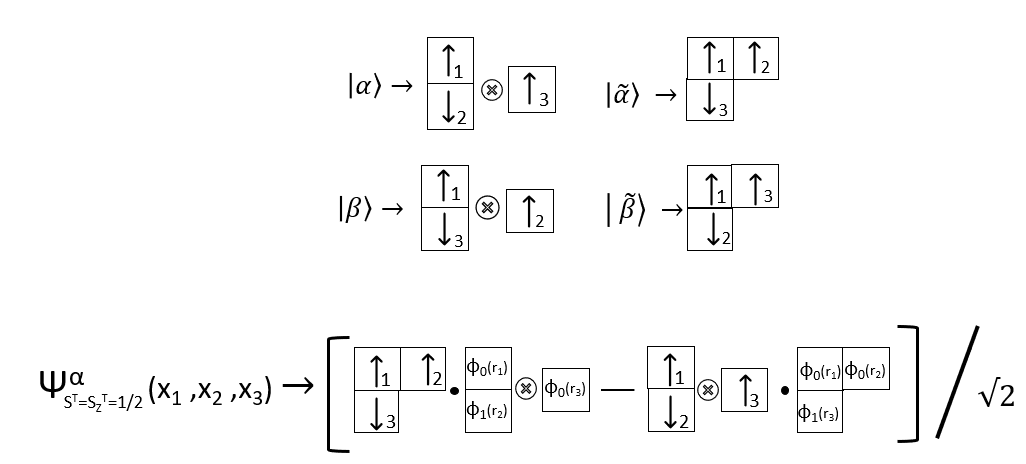

We can construct the same total 3-electron wavefunction instead by starting from spin states $|\beta\rangle$ and $|\tilde \beta\rangle$:


$$\Psi^{\beta}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)=\Big( |\tilde \beta\rangle \Phi_{A_{13}} (x_1,x_2,x_3)  -|\beta\rangle \Phi_{S_{13}} (x_1,x_2,x_3)  \Big) /\sqrt{2}\\  \quad \quad \quad \quad \quad \quad\quad\quad=  - \frac{1}{\sqrt{3!}} \left| \begin{array}{ccc}
 |\uparrow_1\rangle \phi_0(x_1)   & |\uparrow_2\rangle \phi_0(x_2) & |\uparrow_3\rangle \phi_0(x_3)\\
 |\downarrow_1\rangle \phi_0(x_1)   & |\downarrow_2\rangle \phi_0(x_2) & |\downarrow_3\rangle \phi_0(x_3)\\
 |\uparrow_1\rangle \phi_1(x_1)   & |\uparrow_2\rangle \phi_1(x_2) & |\uparrow_3\rangle \phi_1(x_3)\\
\end{array} \right|=-\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3).$$


Important observation: to construct three-electron eigenstate (that satisfies Pauli principle) with $S^T=1/2$, corresponding energy level in Eq. (***) must be (at least doubly) degenerate, so that Schrodinger equation governing the coordinate part of wavefunction should allow solutions with two orthogonal states $\Phi_S$ and $\Phi_A$. As we outlined above (and in accordance with Wigner's result Eq. (11a) for $N_e=3$ and $S^T=1/2$ ) for 3 electrons one can construct 4 linearly independent spin states belonging to $S^T=1/2$ manifold (two with $M=1/2$ and two with $M=-1/2$). In the ground state configuration of 3-electron system these four spin states when combined with their corresponding coordinate parts give rise to only 2 distinct total 3-electron wavefunctions, one with $M=1/2$ (given in Eq. (12)) and another with $M=-1/2$ (obtained by reversing up-spin state into down-spin state in either the first or the last row of the matrix in Eq. (12)). For Lithium atom (with 3 electrons), in single-orbital picture, the ground state is approximated as $1s^22s^1$ state (two electrons occupy the lowest energy $1s$-orbital and the third one occupies $2s$-orbital). $1s^22s^1$ state can not have $S^T=3/2$ (because two electrons in $1s$ state must necessarily form spin-siglet, due to Pauli principle) and hence $1s^22s^1$ state must have $S^T=1/2$ and thus two-fold spin degeneracy $M=\pm 1/2$ (just like hydrgen atom's and other alkali-metal atoms spin degeneracy with 1 electron in the outer $s$-shell). The ground state with $M=1/2$ is obtained from the determinant of a matrix in the right-hand-side of Eq. (12), by substituting $\phi_0(x_j) \to \phi_{1s}(\vec r_j)$, $\phi_1(x_j) \to \phi_{2s}(\vec r_j)$. To approximate the Lithium atom ground state with $M=-1/2$, we have to reverse up-spin state into down-spin state in either the first or the last row of the matrix in Eq. (12).

All these that we have presented so far is well described in textbooks, for example see [4], where a general mathematical scheme can be found for constructing many-body states for identical particles based on irreducible representations of symmetric (permutation) group and associated with them Young tableaux developed by Wigner.

### Truly many-body case: Three-electron coordinate wavefunction not separable into product of single electron orbitals 

Below we will study the case when three-electron coordinate wavefunction is not separable into the product of single-particle orbitals. This case holds generically, when electrons interact with each other and total Hamiltonian describing the many-body system is not a direct sum of Hamiltonians describing individual electron. However, since electrons are indistinguishable partilces, Hamiltonian is still *invariant* under all permutations of the *spatial* variables, just like total spin operator and its $z$ projection are invariant with respect to all permutations of individual spin operators. 

We introduce 1D segment of length $L$ and discretize it with $N$ points to perform numerical simulation of Eq. (***). Interaction between electrons is assumed to be short-ranged with a radius $r_0$:  inter-electron interactions are modeled by repulsive "soft-core" potential $U(x_i-x_j) \sim \Theta(r_0-|x_i-x_j|)$, with a Heaviside function $\Theta$. At the boundaries of 1D segment ($x=0$ and $x=L$) we intorduce a high potential ($V_{boundary}$), to force vanishing of the wavefunction there (mimicking infinite walls).

L = 2;  % 1D segment Length 
N =12;  % Number of coordinate points
h_bar=1;
m=1;
r0=0.1;
x = linspace(0, L, N).'; % Coordinate column vector in x direction
dx = x(2) - x(1); % Coordinate step 
 
e    = ones(N,1);  % a column of 1-s with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  % sparse NxN matrix with -2*e along the main diagonal
% % and vector e along upper and lower diagonals, so called 3-point Laplacian

Lap_1=kron(kron(Lap_1D,speye(N)),speye(N));  % Laplacian of first particle
Lap_2=kron(kron(speye(N),Lap_1D),speye(N));  % Laplacian of second particle
Lap_3=kron(kron(speye(N),speye(N)),Lap_1D);  % Laplacian of third particle 
V_boundary=sparse(kron(kron(heaviside(x-L)+heaviside(0-x),e),e)+kron(kron(e,heaviside(x-L)+heaviside(0-x)),e)+kron(e,kron(e,heaviside(x-L)+heaviside(0-x))));
% V_boundary creates high potential at the boundary of the region, forcing wavefunction to vanish there

V_boundary=100*spdiags(V_boundary,0,N^3,N^3);
[X,Y,Z]=meshgrid(x);  % X,Y,Z are 3D tensors of size [N,N,N] encoding 3D coordinate grid
% X encodes coordinates of first particles, Y - of second and Z - of third 
U=heaviside(r0^2-(X-Y).^2)+heaviside(r0^2-(X-Z).^2)+heaviside(r0^2-(Z-Y).^2);   % U is three dimensional tensor here with size(U)= [N,N,N]
U=spdiags(U(:),0, N^3,N^3);   % U becomes sparse diagonal matrix of linear dimension N^3 


H=-h_bar^2/(2*m)*(Lap_1+Lap_2+Lap_3)+5*U+V_boundary;          % matrix corresponding to the total dimensionless hamiltonian Eq. (*) 

[V,E] = eigs(H,14,'smallestreal'); % find eigenvalues and eigenfunctions of H, 15 smallest
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors. 

E % show energies 
[X2,Y2]=meshgrid(x); % 2D meshgrid for crating convenient surface plots below

V0=reshape(V(:,1),N,N,N);  % the lowest energy state, non-degenerate state, 
% fully symmetric, hence not applicable for 3-electron system
% we are reshaping V(:,1) column into 3D tensor to analyse syetry
% properties with respect of exchanging any two pair of coordinates
surf(X2,Y2,reshape(V0(:,:,N/2),N,N)) % visually check symmetry of the ground state with respect to exchaning x1 and x2 for x3=L
xlabel('x1')
ylabel('x2')
zlabel('The lowest energy fully symmetric state')
surf(X2,Y2,reshape(V0(:,N/2,:),N,N)) % visually check symmetry of the ground state with respect to exchaning x1 and x3 for x2=L
xlabel('x1')
ylabel('x3')
zlabel('The lowest energy fully symmetric state')
surf(X2,Y2,reshape(V0(N/2,:,:),N,N)) % visually check symmetry of the ground state with respect to exchaning x2 and x3 for x1=L
xlabel('x2')
ylabel('x3')
zlabel('The lowest energy fully symmetric state')
V11=reshape(V(:,11),N,N,N); % 11-th excited, non-degenerate state, fully antisymmetric state
surf(X2,Y2,reshape(V11(:,:,N/2),N,N))  % visually check antisymmetry of this state with respect to exchaning x1 and x2
xlabel('x1')
ylabel('x2')
zlabel('V11, fully antisymmetric state')
V11(:,:,N/2)    % confirm antisymmetry of this state with respect to exchaning x1 and x2, here x3=L
surf(X2,Y2,reshape(V11(:,N/2,:),N,N)) % visually check antisymmetry of this state with respect to exchaning x1 and x3 for x2=L
xlabel('x1')
ylabel('x3')
zlabel('V11, fully antisymmetric state')
surf(X2,Y2,reshape(V11(N/2,:,:),N,N)) % visually check antisymmetry of this state with respect to exchaning x2 and x3 for x1=L
xlabel('x2')
ylabel('x3')
zlabel('V11, fully antisymmetric state')
V1=reshape(V(:,2),N,N,N); % the first lowest excited state
reshape(V1(:,:,N/2),N,N)  % check that there is no symmetry or antisymmetry n this state with respect to exchanging x1 and x2 for x3=L
V2=reshape(V(:,3),N,N,N);  % the second lowest excited state, degenerate in energy with the first one
reshape(V2(:,:,N/2),N,N)   % check that there is no symmetry or antisymmetry n this state with respect to exchanging x1 and x2 for x3=L

The lowest energy state is a unique (energetically non-degenerate state) and fully symmetric with respect to exchanging any 2 coordinates of 3 particles, hence it can not describe system of 3 electrons. There are a few other fully symmetric states (e.g. fourth in energy $V(:,4)$ and seventh in energy $V(:,7)$states), which are also unique, non-degenerate in energy. These states must be ignored when studying systems of electrons. 12-th in energy state, vector $V(:,12)$ is also a unique non-degenerate eigenvector, however it is a fully antisymmetric with respect to exchanging any pair of coordinates of 3 particles. Hence it should be coupled with $S^T=3/2$ quadruplet (ferromagnetic multiplet), any of the states of the quadruplet being a fully symmetric state in spin variables.

Fully symmetric and fully antisymmetric coordinate wavefunctions (with respect to exchanging any pair of coordinates) are the only generically non-degenerate solutions of the Schrodinger equation (there is no reason for their degeneracy), whereas any other wavefunction must necessarily be a member of at least two-fold degenerate solutions.

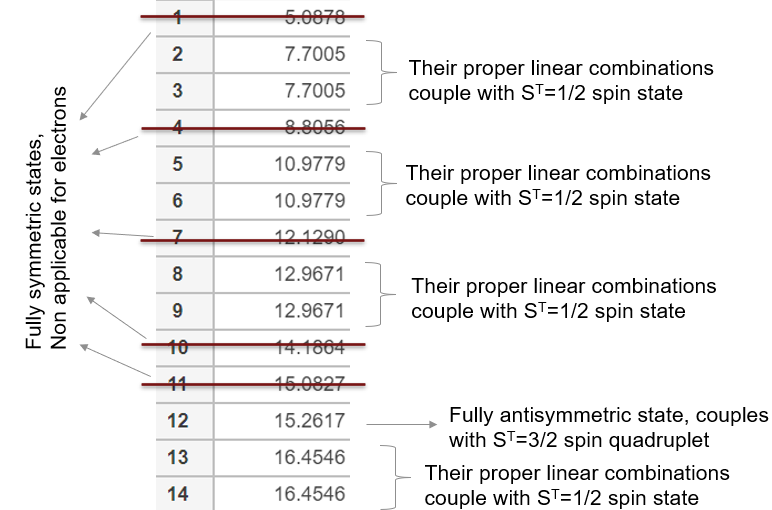

First excited state as we see is doubly degenerate. Wavefunctions $V1=V(:,2)$ and $V2=V(:,3)$, as returned by computer, do not show any apparent symmetry with respect to exchanging any pair of coordinates. 

From linear combinations of two degenerate vectors $V1$ and $V2$ we construnct coordinate wavefunctions $V_{S_{12}}$/ $V_{A_{12}}$ that are symetric/ antisymmetric with respect to exchanging coordinates of 1-st and 2-nd particles. The fact that this is possible is guaranteed by symmetries of the solutions of the differential equations (here reduced to matrix eugenvalue problems), such as Eq. (***), that are invariant with respect to permutations of particles' coordinates.

For this, we search for appropriate real number, angle of admixture between $V1$ and $V2$, $u_{12}$. This number is non-universal, depends on all details of the model studied, including $L$, $N$, interaction strength, etc.

u_12=0.3783514434919;
V_S12=-V1-u_12*V2;
V_A12=u_12*V1-V2;

reshape(V_S12(:,:,N/2),N,N)   % symmetric matrix (with respect to exchanging x1 and x2) for any value of x3, here x3=L
reshape(V_S12(:,:,N/2),N,N) -reshape(V_S12(:,:,N/2),N,N).' % matrix minus it's transpose
reshape(V_A12(:,:,N/2),N,N)   % antisymmetric matrix for any value of x3, here x3=L
reshape(V_A12(:,:,N/2),N,N) +reshape(V_A12(:,:,N/2),N,N).' % matrix plus it's transpose

Functions $V_{S_{12}}$/$V_{A_{12}}$ are three-body coordinate wavefunctions, symmetric/ antisymmetric with exchange $x_1 \leftrightarrow x_2$, degenerate in energy with (and orthogonal to) each other, solutions of Schrodinger equation Eq. (***), and highly unlikely to be separable into the direct product of single-particle wavefunctions. Let us construct with their help and with $|\alpha \rangle$and $|\tilde \alpha\rangle$a total 3-electron wavefunction as follows (in analogy to the prescription by Wigner discussed above)


$$(13)\quad \Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3) =\frac{1}{\sqrt{12}} \Big(   |\uparrow_1\rangle \otimes |\downarrow_2 \rangle \otimes  |\uparrow_3\rangle + |\downarrow_1\rangle\otimes | \uparrow_2\rangle \otimes |\uparrow_3 \rangle  -2 |\uparrow_1\rangle \otimes |\uparrow_2\rangle \otimes |\downarrow_3 \rangle \Big) V_{A_{12}}(x_1,x_2,x_3)\\ 
\quad\quad\quad\quad\quad\quad\quad\quad  -\frac{1}{\sqrt{4}} \Big(  | \uparrow_1\rangle \otimes | \downarrow_2 \rangle \otimes | \uparrow_3\rangle - |\downarrow_1\rangle \otimes |\uparrow_2\rangle \otimes | \uparrow_3\rangle   \Big) V_{S_{12}} (x_1,x_2,x_3).$$


By construction $\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$ is explicitely symmetric with respect to exchanging first and second electrons, ($s_1 \leftrightarrow s_2$ and$x_1 \leftrightarrow x_2$). We need to check if antisymmetry holds for exchanging any two electrons.

Since total 3-electron wavefunction in Eq. (13) is not written in the form of a matrix determinant (as opposed to Eq. (12) where 3-body cordinate wavefunctions were represented by the products of single-electron orbitals) this check needs numerical confirmation.

Let's exchange 1-st and 3-rd electrons. Then, relations like below must be satisfied in order to have antisymmetry of the total wavefunction:

$\frac{2}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)-V_{S_{12}}(x_3,x_2,x_1) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_3,x_2,x_1)=0$,

$-V_{S_{12}}(x_1,x_2,x_3) +\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)=V_{S_{12}}(x_3,x_2,x_1) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_3,x_2,x_1)$,

$V_{S_{12}}(x_1,x_2,x_3) +\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)=-V_{S_{12}}(x_1,x_3,x_2) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_3,x_2)$.

We check below numerically that indeed such equations are satisfied.

% here x2=L, these equations however hold for any value of x2
2/sqrt(3)*reshape(V_A12(:,N/2,:),N,N)-reshape(V_S12(:,N/2,:),N,N).'-1/sqrt(3)*reshape(V_A12(:,N/2,:),N,N).' 
% zero within 10^(-14) accuracy, depending on precise value of u_12
reshape(-V_S12(:,N/2,:),N,N)+1/sqrt(3)*reshape(V_A12(:,N/2,:),N,N)  % antisymmetric matrix (with respect to exchanging x1 and x3) for any fixed x2, here x2=L
reshape(V_S12(N/2,:,:),N,N)+1/sqrt(3)*reshape(V_A12(N/2,:,:),N,N)  % antisymmetric matrix (with respect to exchanging x2 and x3) for any fixed x1, here x1=L 

Analogically, we can construnct coordinate wavefunctions $V_{S_{13}}$/$V_{A_{13}}$ that are symmetric/ antisymmetric with respect to exchanging coordinates of 1-st and 3-rd particles and are linear combination between $V1$ and $V2$. Again we search for appropriate real number, which we denote as $u_{13}$. Total (accounting for both spins and coordinates) 3-electron wavefunction represented with $|\beta\rangle$ and $|\tilde \beta \rangle$ will look:

$\Psi^{\beta}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)=|\tilde \beta\rangle V_{A_{13}} (x_1,x_2,x_3)/\sqrt{2} -|\beta\rangle V_{S_{13}} (x_1,x_2,x_3)/\sqrt{2} =-\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$.

For the last equality (showing that $\Psi^{\beta}=-\Psi^{\alpha}$, hence both total 3-electron states describe the same wavefunction) we have used the following relations that we checked numerically to hold for any values of $x_j$:

$V_{S_{12}}(x_1,x_2,x_3)+V_{A_{12}}(x_1,x_2,x_3)/\sqrt{3}+V_{S_{13}}(x_1,x_2,x_3)+V_{A_{13}}(x_1,x_2,x_3)/\sqrt{3}=0$,

$-V_{S_{12}}(x_1,x_2,x_3)/2+V_{A_{12}}(x_1,x_2,x_3)/\sqrt{12}-V_{A_{13}}(x_1,x_2,x_3)/\sqrt{3}=0$,

$V_{A_{12}}(x_1,x_2,x_3)/\sqrt{3}+V_{S_{13}}(x_1,x_2,x_3)/2-V_{A_{13}}(x_1,x_2,x_3)/\sqrt{12}=0$.

u_13=6.122856773029

V_S13=V1+u_13*V2;
V_A13=u_13*V1-V2;

reshape(V_S13(:,N/2,:),N,N)   % symmetric matrix (with respect to exchanging x1 and x3) for any value of x2, here x2=L
reshape(V_S13(:,N/2,:),N,N)-reshape(V_S13(:,N/2,:),N,N).'
reshape(V_A13(:,N/2,:),N,N)   % antisymmetric matrix for any value of x2, here x2=L
reshape(V_A13(:,N/2,:),N,N)+reshape(V_A13(:,N/2,:),N,N).'
2/sqrt(3)*reshape(V_A13(N/2,:,:),N,N)+reshape(V_S13(N/2,:,:),N,N).'-1/sqrt(3)*reshape(V_A13(N/2,:,:),N,N).' 
% zero within 10^(-9) accuracy, depending on precise value of u_13

Finally, the coordinate wavefunctions $V_{S_{23}}$/ $V_{A_{23}}$ that are symmetric/ antisymmetric with respect to exchanging coordinates of 2-nd and 3-rd electrons can be obtained as: $V_{S_{23}}=V_{S_{12}}/|V_{S_{12}}| +V_{S_{13}}/|V_{S_{13}}|$ and $V_{A_{23}}=V_{A_{12}} /|V_{A_{12}}|-V_{A_{13}}/|V_{A_{13}}|$.

V_S12(:)=V_S12(:)/sqrt(V_S12(:).'*V_S12(:)); % first normalize vectors to unity
V_A12(:)=V_A12(:)/sqrt(V_A12(:).'*V_A12(:));
V_S13(:)=V_S13(:)/sqrt(V_S13(:).'*V_S13(:));
V_A13(:)=V_A13(:)/sqrt(V_A13(:).'*V_A13(:));

V_S23=reshape(V_S13+V_S12,N,N,N); % reshape N^3 element column vector into 3D tensor for convenience
reshape(V_S23(N/2,:,:),N,N)-reshape(V_S23(N/2,:,:),N,N).' %check that V_S23 is symmetric with respect to exchaning x2 and x3 for x1=L. Same symmetry is retained for any value of x1
V_A23=reshape(-V_A13+V_A12,N,N,N); 
reshape(V_A23(N/2,:,:),N,N)+reshape(V_A23(N/2,:,:),N,N).'  %check that V_A23 is antisymmetric with respect to exchaning x2 and x3, here for x1=L. Same antisymmetry is retained for any value of x1
reshape(V_S12(:,:,N/2),N,N)-reshape(V_S13(:,N/2,:),N,N)
reshape(V_A12(:,:,N/2),N,N)-reshape(V_A13(:,N/2,:),N,N)
reshape(V_A12(:,N/2,:),N,N)/sqrt(3)-reshape(-V_S13(:,N/2,:),N,N)/2-reshape(V_A13(:,N/2,:),N,N)/sqrt(12)
reshape(-V_S12(:,N/2-3,:),N,N)/2+reshape(V_A12(:,N/2-3,:),N,N)/sqrt(12)-reshape(V_A13(:,N/2-3,:),N,N)/sqrt(3)

reshape(V_S12(:,:,N/2),N,N)+reshape(V_A12(:,:,N/2),N,N)/sqrt(3)...
+reshape(V_S13(:,:,N/2),N,N)+reshape(V_A13(:,:,N/2),N,N)/sqrt(3)

#### Low lying energy levels of 3 electrons with very strong repulsive interactions

Finally we study low lying energy levels when repulsion between electrons is extremely strong. We put $U(x_i-x_j) =500\Theta(r_0-|x_i-x_j|)$, keeping same $r_0=0.1$ and same other parameters ($L,N,...$) as in above simulations. In this situation we expect that for $S^T=1/2$ there will be 4 distinct total 3-electron state with (almost) degenerate energy, since electrons will avoid to occupy same space (same orbitals in single-particle picture).

First and seventh unique states are fully symmetric with respet to exchanging any pair of coordinates and should be discarded from fermionic problems. The fully antisymmetric in coordinate exchgane state (which for previous calculations with moderate repulsion strength $U(x_i-x_j) =5\Theta(r_0-|x_i-x_j|)$ was 12-th in energy) is now 6-th in energy (in a total 3-electron wavefunction this fully antisymmetric in coordinate exchange state will be coupled with $S^T=3/2$ spin ferromagnetic quadruplet) and it is almost degenerate with the 4 "mixed-symmetry" states that are slightly lower in energy. For even stronger repulsion degeneracy between 5 solutions of coordinate Shrodinger equation ($V(:2)$,... $V(:,6)$) becomes even more pronounced.

For very strong repulsion all $2^3=8$ spin states become energetically (almost) degenerate and in the total 3-electron wavefunction these spin states are coupled with the first 5 allowed coordinate states: $V(:2)$,... $V(:,6)$ as indicated in the table below. 

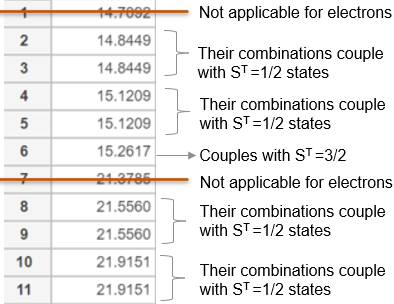

As indicated in the above table, linear superpositions of states $V(:,2)$ and $V(:,3)$ as well as superpositions of states $V(:,4)$ and $V(:,5)$ couple with spin states with $S^T=1/2$ (for both values of $M=\pm1/2$), producing four linearly independent total 3-electron wavefunctions with $S^T=1/2$ quasi-degenerate in energy with each other and with ferromagnetic quadruplet of $S^T=3/2$.

## References

[1] For hyperfine corrections in hydrogen and alkali-metal atoms see: ["Breit-Rabi diagram for alkali-metal atoms"](https://www.mathworks.com/matlabcentral/fileexchange/87819-breit-rabi-diagram-for-alkali-metal-atoms).

[2] A. Kramida, et al. ["NIST Atomic Spectra Database Ionization Energies Data"](http://physics.nist.gov/PhysRefData/ASD/ionEnergy.html). Gaithersburg, MD: NIST.

[3] R.G. Parr and W. Yang, *Density‐functional theory of atoms and molecules,* Oxford University Press, (1989).

[4] R. McWeeny,  *Methods of molecular quantum mechanics*, Academic Press Second Edition (1989).